clc
clear
Kt = 0.011;
Km = 327*10^-6;
m = 1.513;
Ixx = 0.0185;
Iyy = 0.0201;
Izz = 0.0286;
g = 9.82;
lroll = 0.175;
lpitch = 0.175;

A = [zeros(6,6)  [0 0 0 0 -g 0; 0 0 0 g 0 0 ; zeros(4,6)];
    eye(6) zeros(6,6)];
B = [zeros(4,2) [Kt/m -(lroll*Kt)/(Ixx) -(lpitch*Kt)/(Iyy) (Km)/(Izz); 
    Kt/m (lroll*Kt)/(Ixx) (lpitch*Kt)/(Iyy) (Km)/(Izz); 
    Kt/m (lroll*Kt)/(Ixx) -(lpitch*Kt)/(Iyy) -(Km)/(Izz); 
    Kt/m -(lroll*Kt)/(Ixx) (lpitch*Kt)/(Iyy) -(Km)/(Izz)] zeros(4,6)].';

C = [0 0 0 0 0 0 1 0 0 0 0 0 ;
     0 0 0 0 0 0 0 1 0 0 0 0 ;
     0 0 0 0 0 0 0 0 1 0 0 0 ;
     0 0 0 0 0 0 0 0 0 1 0 0 ;
     0 0 0 0 0 0 0 0 0 0 1 0 ;
     0 0 0 0 0 0 0 0 0 0 0 1 ;];
D = zeros(6,4);

s=tf('s');
tfs = (C/(s*eye(12)-A))*B;

omega_roll_u = tfs(1,2);
omega_pitch_u = tfs(2,2);
omega_yaw_u = tfs(3,1);

theta_omega_roll = tfs(4,2)/omega_roll_u;
phi_omega_pitch = tfs(5,2)/omega_pitch_u;
psi_omega_yaw = tfs(6,2)/omega_yaw_u;

x_phi = tfs(4,1)/tfs(5,2)
y_theta = tfs(5,2)/tfs(4,2)

Kp_outer = 1;
Ki_outer = 0;
Kd_outer = 0;
Kp_inner = 500;
Ki_inner = 100;
Kd_inner = 0;
N = 20;


$$Inner_{plant} = \frac{\omega_\phi}{u}$$


Inner_plant = omega_pitch_u;

Inner_plant =
 
  1.022 s^2
  ----------
  0.1041 s^4
 
Continuous-time transfer function.
Model Properties



$$Outer_{plant} = \frac{\phi}{\omega_\phi}=\frac{\phi}{u}/\frac{\omega_\phi}{u}$$


Outer_plant = phi_omega_pitch;

Outer_plant =
 
  0.9405
  ------
   s^2
 
Continuous-time transfer function.
Model Properties


sim_time = 10;
reference_Input_Grader = 20;
stepRef = pi/180*reference_Input_Grader;
Saturation = 1000;

simData = sim('PID_Sim_Cascade');
ref = simData.yout{3}.Values.Data;
refInner = simData.yout{6}.Values.Data;
uout = simData.yout{2}.Values.Data;
yInnerOut = simData.yout{5}.Values.Data;
yout = simData.yout{1}.Values.Data;
uoutSat = simData.yout{4}.Values.Data;
tout = simData.tout;

figure()
S = stepinfo(yout, tout, stepRef)

S = struct with fields:
         RiseTime: 1.0508
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: -2.1678e-04
      SettlingMax: 0.6983
        Overshoot: 100.0516
       Undershoot: 0.0621
             Peak: 0.6983
         PeakTime: 9.7472


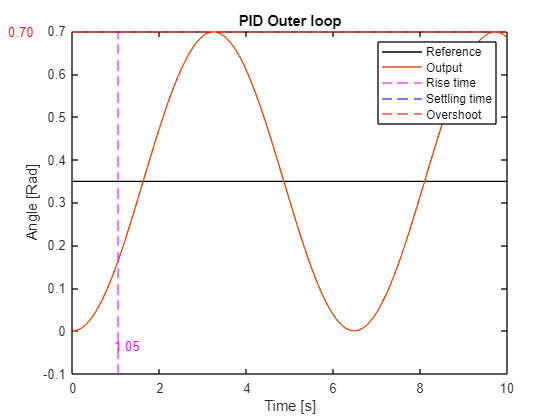

plot(tout,ref,'black',tout, yout)
title('PID Outer loop')
xlabel('Time [s]');
ylabel('Angle [Rad]');
xline(S.RiseTime,'--',Color='[1,0,1]')
xline(S.SettlingTime,'--',Color='b')
yline(S.Peak,'--',Color='[1,0,0]')
text(-1.5, S.Peak, sprintf('%.2f', S.Peak),Color='[1,0,0]');
text(S.RiseTime-0.1, -0.035, sprintf('%.2f', S.RiseTime),Color='[1,0,1]');
text(S.SettlingTime-0.1, -0.017, sprintf('%.2f', S.SettlingTime),Color='b');
legend('Reference','Output','Rise time','Settling time','Overshoot')

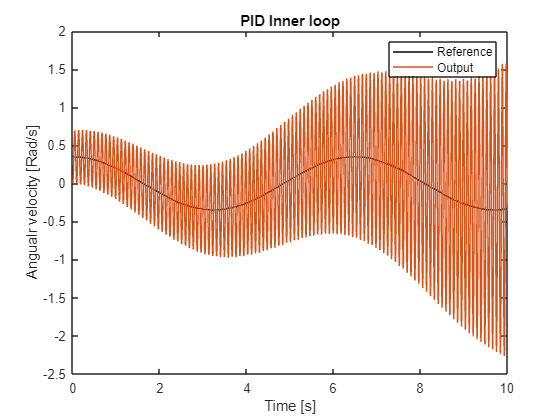


figure()
% S = stepinfo(yInnerOut, tout, refInner(1))
plot(tout,refInner,'black',tout, yInnerOut)
title('PID Inner loop')
xlabel('Time [s]');
ylabel('Angualr velocity [Rad/s]');
% xline(S.RiseTime,'--',Color='[1,0,1]')
% xline(S.SettlingTime,'--',Color='b')
% yline(S.Peak,'--',Color='[1,0,0]')
% text(-1.5, S.Peak, sprintf('%.2f', S.Peak),Color='[1,0,0]');
% text(S.RiseTime-0.1, -0.035, sprintf('%.2f', S.RiseTime),Color='[1,0,1]');
% text(S.SettlingTime-0.1, -0.017, sprintf('%.2f', S.SettlingTime),Color='b');
% legend('Reference','Output','Rise time','Settling time','Overshoot')
legend('Reference','Output')

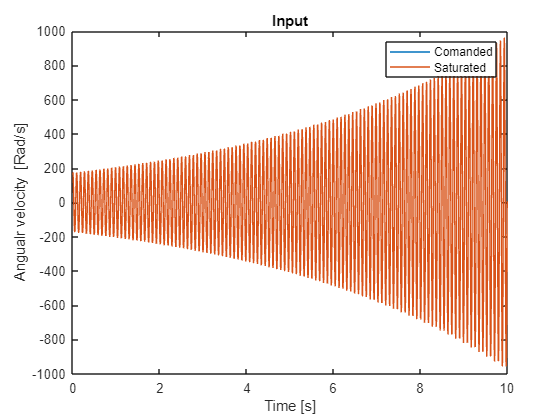


figure()
plot(tout,uout,tout,uoutSat)
legend('Comanded', 'Saturated')
title('Input')
xlabel('Time [s]');
ylabel('Angualr velocity  [Rad/s]');